## Question 1

The cyclin-dependent kinase, CDK1, drives a cell into mitosis. Anaphase-promoting complex (APC), on the other hand, drives the cell out of mitosis. The protein circuit of the cell cycle defined based on APC and CDK1 is characterized by CKD1 promoting APC, and APC in turn, inhibiting CDK1. Further, there are other positive and double-negative feedback elements controlling CDK1 levels, as well as potential intermediates in the simplified illustration of the interaction between APC and CDK1 shown in figure 1. Together, they induce a time lag between the activities of CDK1 and APC.

CDK1 activity increases at first and the cell goes into mitosis. As CDK1 levels rise, after a time delay, it promotion of APC causes APC activity to rise. Rising APC inhibits CDK1 and causes it to drop down. At this point, the cell is driven out of mitosis. Now, the low CDK1 activity, with some time lag, causes a drop in APC. The process then repeats all over again, as CDK1 begins to rise again. Hence, the combination of the protein interactions and time delay between the effects effectively explains the cell-cycle oscillations.

## Question 2

In the simplest 2-ODE model, the system exhibits a damped oscillation. This is because the activities of CDK1 and APC instantly act on one another and the system quickly converges toward its stable state; evident as an inward spiral into the stable fixed point. Furthermore, linear stability analysis validates the dampening effect of the oscillation.

Upon introducing a time delay between the activities and their effects using delay differential equations, the system begins to oscillate when the time delay is sufficiently large. This shows that a time delay between the activity and effect that keeps the system from settling into a stable fixed state for long enough for its components to move away from the convergence point so as to set off a new cycle of the same events is key to ensure undamped oscillations.

The 2-ODE model with a bistable trigger manages to just that. The positive feedback from CDK1 to itself transitions the system from a fully gradual approach towards the steady state, to a slow followed by rapid approach toward the stable state. The slow phase introduces the required time lag and the subsqeuent rapid movement toward the stable point, in combination with the time lag, manages to disrupt the system from the equilibrum enough to set off another oscillation, and the process repeats all over again. Analytically, this can be seen from the fact that the stable fixed point of the simple 2-ODE model now becomes an unstable fixed point. And on either side of the unstable fixed point, CDK1 activity behaves like a toggle switch. Consequently, the system oscillates about this unstable fixed point.

The 3-ODE model also introduces a time lag that leads to oscillations, only this time in the form of an intermediate interaction that introduces a time delay.

## Question 3

### Bistable Trigger Model

Ferrell et al 2011 (Cell)


$$\frac{dCDK1}{dt} = \alpha_1 -\beta_1 * CDK1* \left[\frac{APC^{n1}}{K_1^{n1}+APC^{n1}}\right] + \alpha_3*(1-CDK1)*\frac{CDK1^{n3}}{K_3^{n3}+CDK^{n3}}\\

\frac{dAPC}{dt} = \alpha_2 * (1-APC)  * CDK1* \left[\frac{CDK1^{n2}}{K_2^{n2}+CDK1^{n2}}\right] - \beta_2 * APC $$


Parameters:

param_bt.a1 = 0.02;
param_bt.b1 = 3;
param_bt.K1 = 0.5;
param_bt.n1 = 8;
param_bt.a2 = 3;
param_bt.b2 = 1;
param_bt.K2 = 0.5;
param_bt.n2 = 8;
param_bt.a3 = 3;
param_bt.K3 = 0.5;
param_bt.n3 = 8;

Solve and Plot bistable trigger ODE:

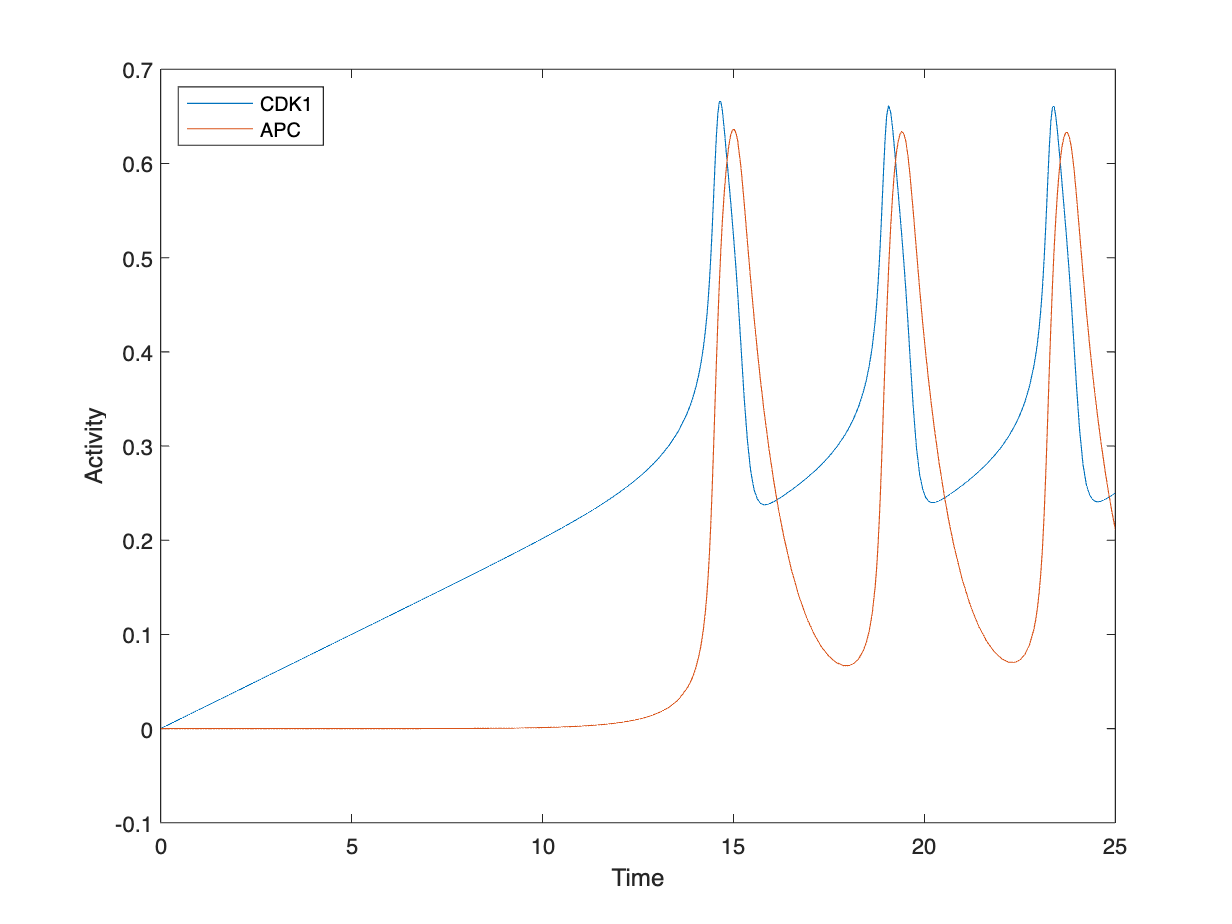

x0 = [0,0];
T0 = 0;
% initial time
Tf = 25;
% final time = 25
[tout,x] = ode45(@(t,y) differential_equation_bt(t,y,param_bt),[T0 Tf],x0);
% this function uses variable step sizes, but in general, we like uniform
% step sizes, so we interpolate the result here...
tpositions = 0:0.01:25;
xi = interp1(tout,x,tpositions);

figure;
zoom on;
plot(tpositions,xi);
ylabel('Activity');
xlabel('Time')
leg = legend('CDK1','APC');
leg.Location ='Northwest';

Plot the CDK1/APC Phase Space 

**Note**: 

- Changed the cdk nullcline to be solved first for apc to obtain the equation as a function of cdk. This is better than the alternative, because the nullcline has a unique APC value for each CDK1 value, while the reverse is not true. Solving for apc first allows us to choose which solution to use to make the plot. On the contrary, the plot repeats some points when using the alternative as provided in the initial code (i.e. solving for cdk first, and then substituting apc) -- also plotting that in magenta to illustrate; it starts repeating values for APC>0.2.

- Plotting the nullclines for all values between 0 and 1 to reproduce the entire phase space, rather than just for the interpolated axis values.

syms cdk apc;

% nullcline 1.
eqs1 = param_bt.a1 - param_bt.b1*cdk*((apc^param_bt.n1)/(param_bt.K1^param_bt.n1+apc^param_bt.n1)) ...
+ param_bt.a3*(1-cdk)*((cdk^param_bt.n3)/(param_bt.K3^param_bt.n3+cdk^param_bt.n3)) == 0;

% nullcline 2.
eqs2 = param_bt.a2*(1-apc)*cdk^param_bt.n2/(param_bt.K2^param_bt.n2+cdk^param_bt.n2) - param_bt.b2*apc == 0;

% solve nullclines.
cdk_null_apc = vpasolve(eqs1, cdk);
cdk_null = vpasolve(eqs1, apc); % function of cdk, not apc; use the positive real soln. only.
apc_null = vpasolve(eqs2, apc); % function of cdk
figure;
zoom on; box on;
hold on;

%unequally time-spaced points. Plotting every point
plot(xi(:,1),xi(:,2),'g');
plot(subs(cdk_null_apc, apc, 0:0.01:1), 0:0.01:1, 'm');

plot(0:0.01:1, subs(cdk_null(1), cdk, 0:0.01:1), 'b');

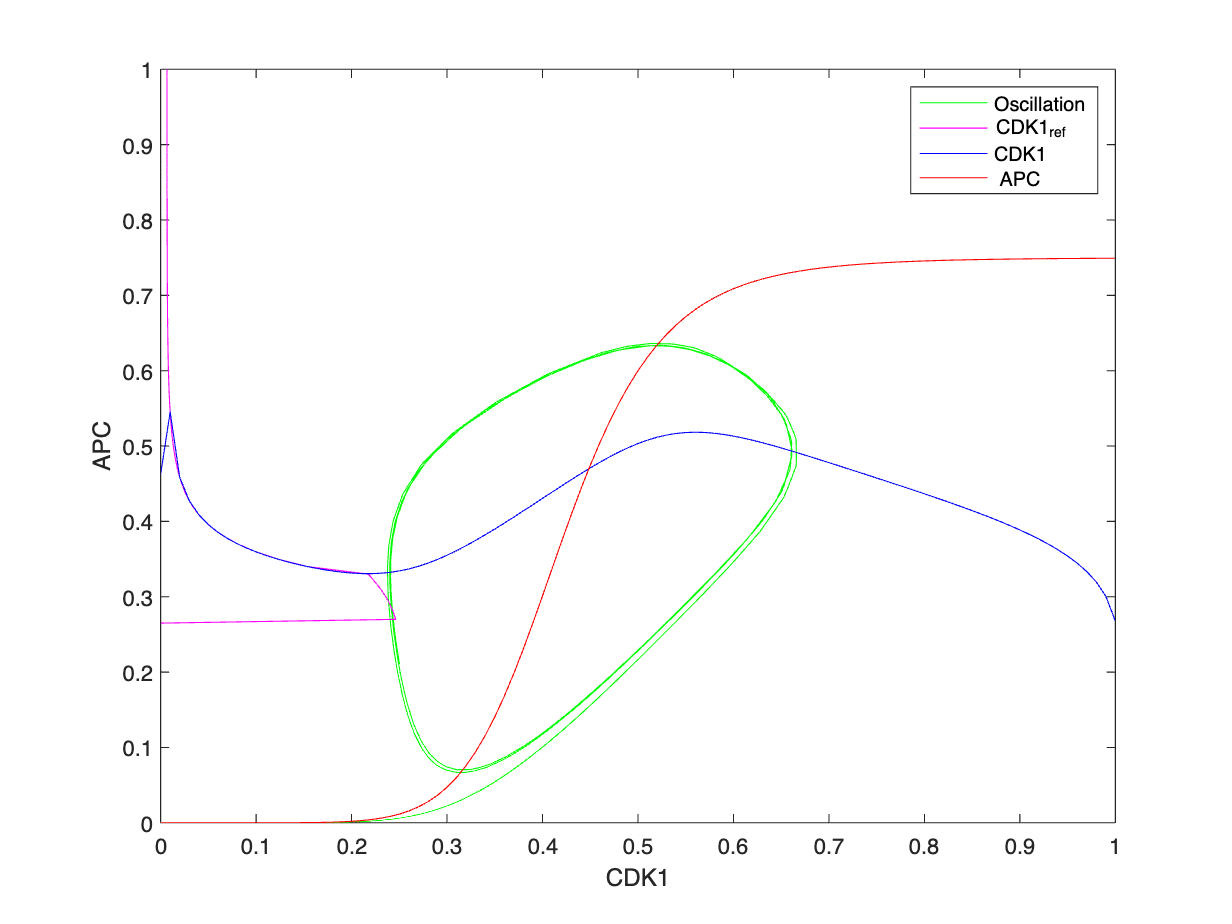

plot(0:0.01:1, subs(apc_null, cdk, 0:0.01:1), 'r');

xlim([0,1]);
ylim([0,1]);
ylabel('APC');
xlabel('CDK1');
leg = legend('Oscillation', 'CDK1_ref', 'CDK1',' APC');

### Parameter Tuning

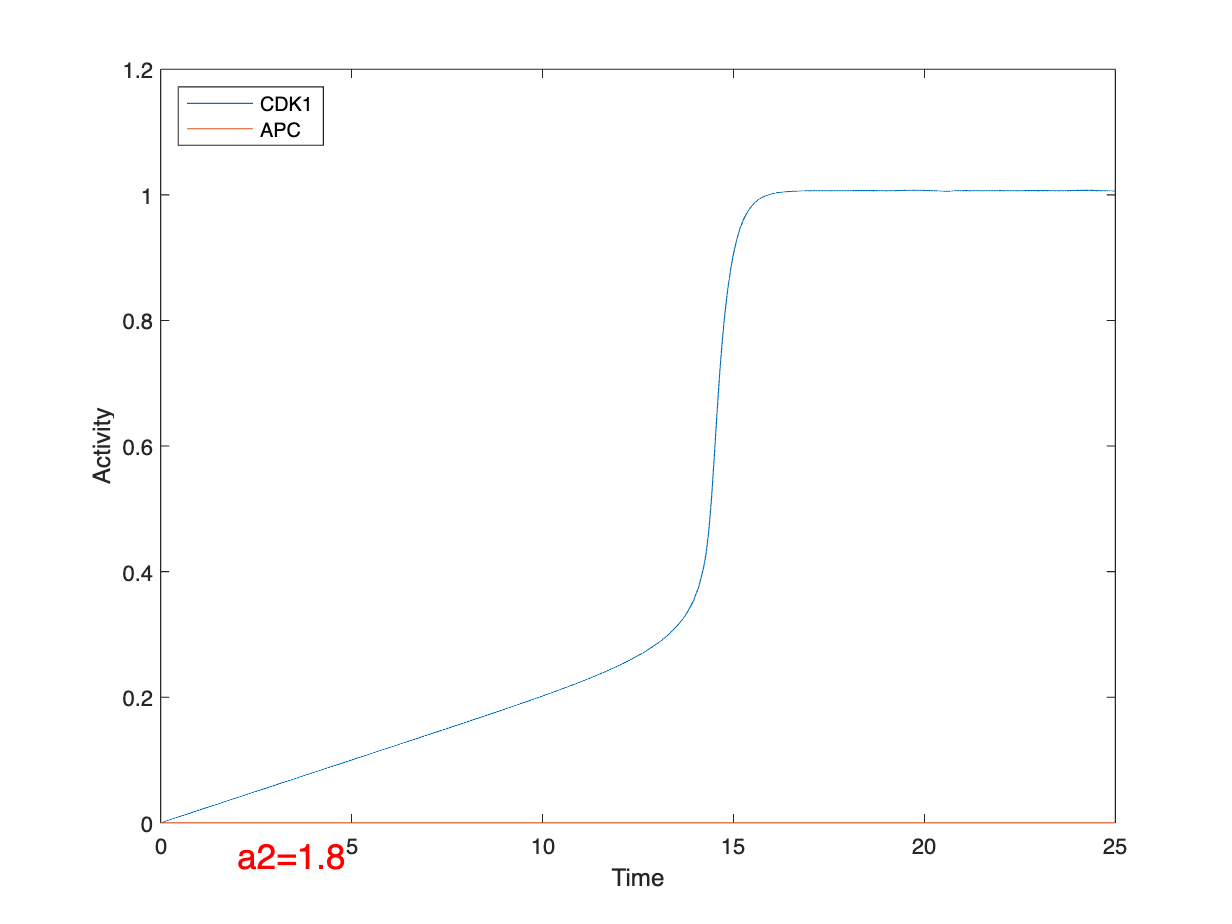

param_bt.a1 = 0.02;
param_bt.b1 = 3;
param_bt.K1 = 0.5;
param_bt.n1 = 8;
param_bt.a2 = 0;
param_bt.b2 = 1;
param_bt.K2 = 0.5;
param_bt.n2 = 8;
param_bt.a3 = 3;
param_bt.K3 = 0.5;
param_bt.n3 = 8;

x0 = [0,0];
T0 = 0;
% initial time
Tf = 25;
% final time = 25
[tout,x] = ode45(@(t,y) differential_equation_bt(t,y,param_bt),[T0 Tf],x0);
% this function uses variable step sizes, but in general, we like uniform
% step sizes, so we interpolate the result here...
tpositions = 0:0.01:25;
xi = interp1(tout,x,tpositions);

figure;
zoom on;
plot(tpositions,xi);
ylabel('Activity');
xlabel('Time')
leg = legend('CDK1','APC');
leg.Location ='Northwest';
text(2, -0.05, 'a2=1.8','Color','red', 'FontSize', 16);

### Observed Effects of Parameters.

**a1**: Higher value leads to higher frequency of oscillations. Lower values delays the onset of oscillations. When set to zero, CDK1 activity remains at 0 throughout since there is nothing to activate it.

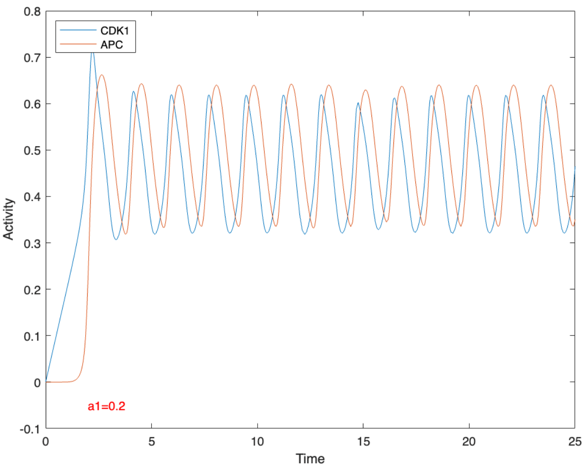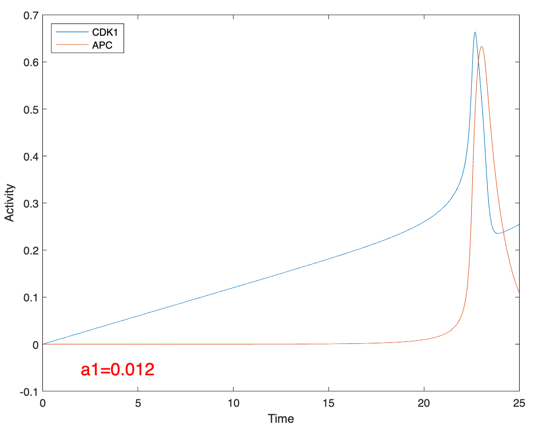

**a2:** Increasing it has a damping effect. So does decreasing it. When set to zero, APC is never active. CDK1 behaves like a 1D-ODE.

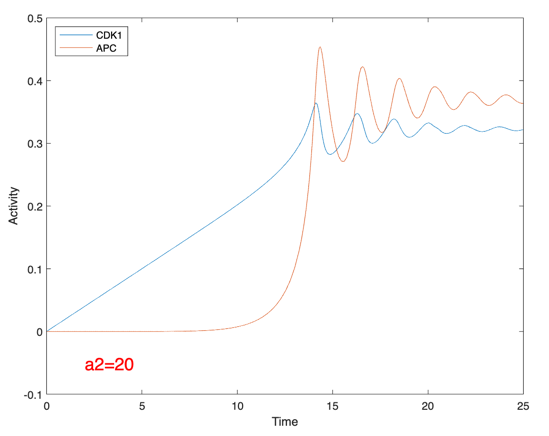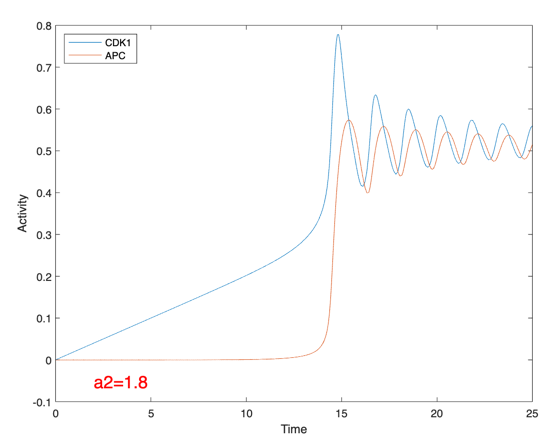

**a3**: Decreasing it has a dampening effect, likely because the magnitude of positive feedback is reduced. Increasing it causes the period of each oscillation to increase.

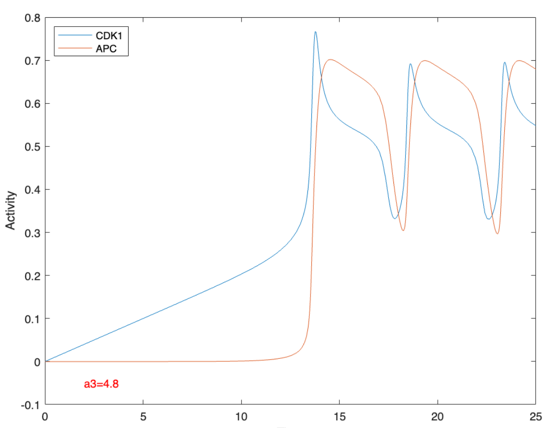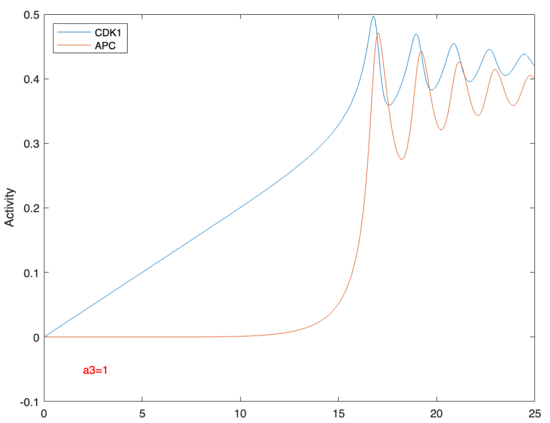

**b1: **Decreasing it causes damping. Increasing it reduces oscillation frequency. Setting it to zero completely eliminates inhibition pf CDK1 by APC, causing CDK1 to saturate at high value. Consequently, APC settles at a high value as well.

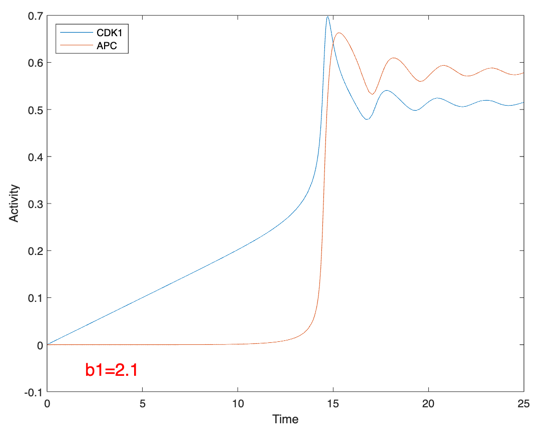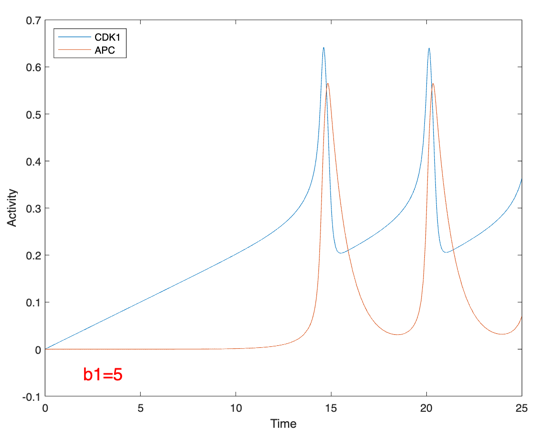

**b2: **Decreasing it reduces oscillation frequency. Increasing it causes damping. Setting to 0 completely eliminates mass action kinetics; hence, APC rises to a maximum and is never inhibited.

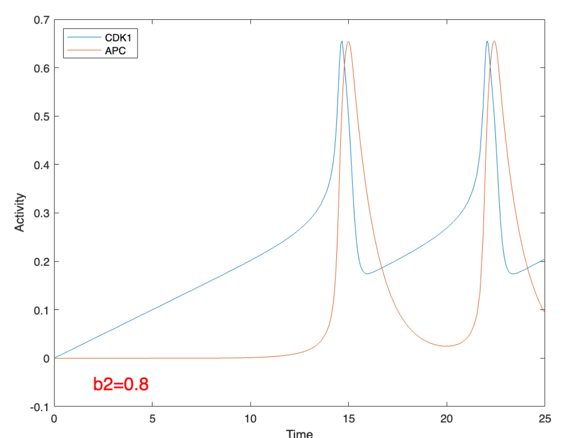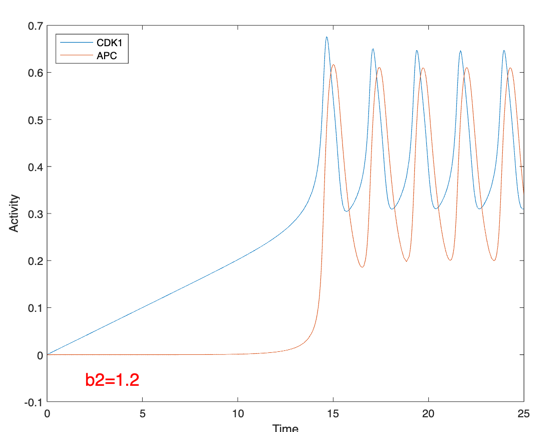

**n1 (and n2)**: Decreasing it reduces frequency of oscillations, and vice-versa. If n1=0, APC activity is always 0. Similarly, when n2=0, CDK1 activity is always 0.

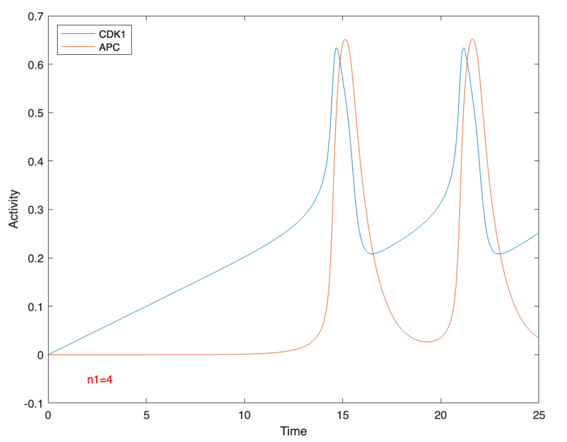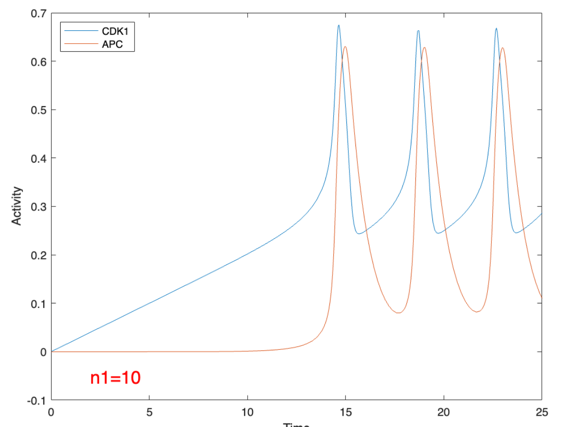

**n3: **Increasing it reduces frequency of oscillations, but decreasing it has a damping effect. Setting it to zero damps it very quickly. This is likely because the hill function disappears, eliminating the ultrasensitive effect.

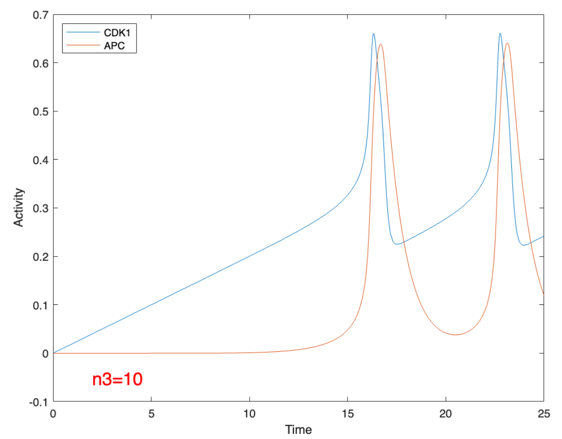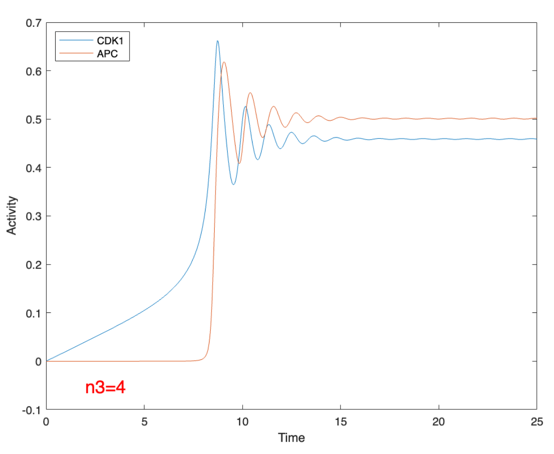

**K1 and K2**: Increasing it causes a damping effect. So does decreasing it. When set to zero, the effect of the whole ultrasensitive effect term disappears, since the numerator and denominator of the hill function become equal.

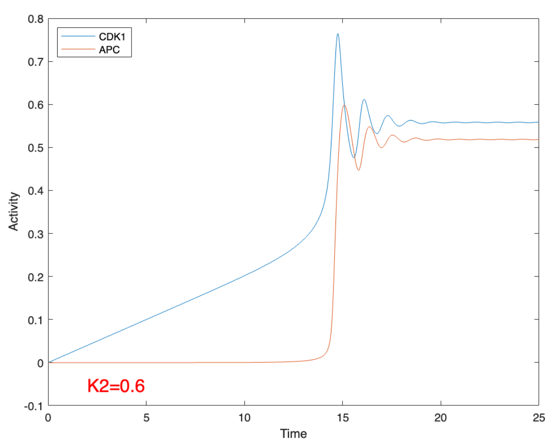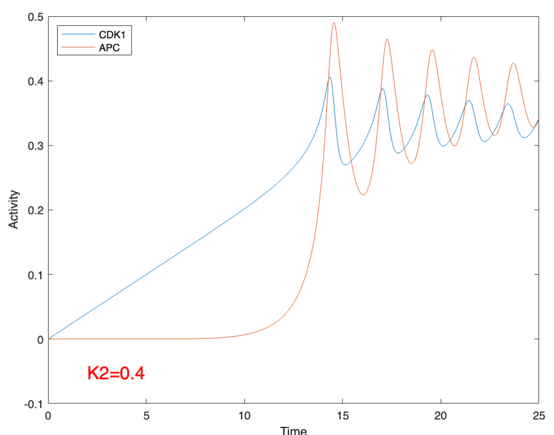

Bistable Trigger system of equations:

function dydt_bt = differential_equation_bt(t,y,p)
    dydt_bt = zeros(2,1);
    dydt_bt(1) = p.a1 - p.b1*y(1)*y(2)^p.n1/(p.K1^p.n1+y(2)^p.n1) + p.a3*(1-y(1))*y(1)^p.n3/(p.K3^p.n3+y(1)^p.n3);
    dydt_bt(2) = p.a2*(1-y(2))*y(1)^p.n2/(p.K2^p.n2+y(1)^p.n2) - p.b2*y(2);
end